%% AAE 532 HW 4 Problem 3
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps4';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
format shortEng;

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
earth = planet_consts.earth;  % structure of earth
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a)
h = 225;  % altitude [km]
r_E = earth.mer;  % radius of earth [km]
mu = earth.gp;
r_c = r_E + h;
v_c = sqrt(mu / r_c);
v_esc = sqrt(2) * v_c;

% (b)
r_p = h;
p = 2 * r_p

p =    450.0000e+000


dist = r_E * [2, 10, 75, 200, 800, 2000];
v_para = []; TA = []; t_rp = [];
for ri = dist
    v_para = [v_para, parabola_for_r(ri, mu)];
    temp = true_anomaly_calc(p, ri);
    TA = [TA, temp];
    t_rp = [t_rp, backer_eqn_time(p, mu, temp)];
end
t_rp = t_rp / 60 / 60/ 24;

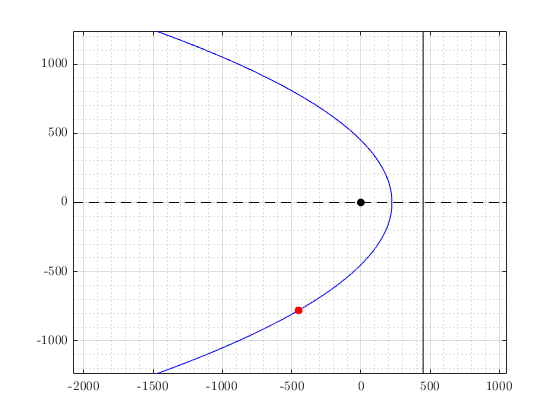

% (c)

% Plotting 
TA = -140:0.01:140;
R = p ./ (1 + cosd(TA));
X = R .* cosd(TA);
Y = R .* sind(TA);

% Find point for -120 degrees
R_n120= R(TA == -120);

fig1 = figure("Renderer","painters");
title('Parabolic Orbit for $-140^{\circ}<\theta^*<140^{\circ}$ - T. Koike')
xlabel('x-direction')
ylabel('y-direction')
plot(X, Y, '-b')
grid on; grid minor; box on; axis equal;
hold on;
plot(R_n120*cosd(-120), R_n120*sind(-120), '.r', 'MarkerSize', 20)

% Directrix 
direx_y = fig1.CurrentAxes.YLim(1):fig1.CurrentAxes.YLim(2);
direx_x = ones(size(direx_y))*2*r_p;
plot(direx_x, direx_y, '-k')

% x-axis 
xaxis_x = fig1.CurrentAxes.XLim(1):fig1.CurrentAxes.XLim(2);
xaxis_y = zeros(size(xaxis_x));
plot(xaxis_x, xaxis_y, '--k')

% Center
plot(0, 0, '.k', 'MarkerSize', 20)
hold off
saveas(fig1, fullfile(fdir, 'p3_plot.png'))

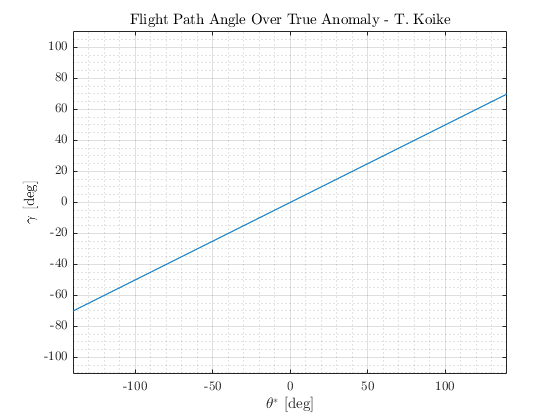

% Plotting gamma with TA

% gamma 
rs = calc_parabola_r(p, TA);
vs = parabola_for_r(rs, mu);
gammas = acosd(sqrt(mu*p) ./ rs ./ vs);
idx1 = find(TA == -140);
idx2 = find(TA==0);
gammas(idx1:idx2) = -1*gammas(idx1:idx2);

fig2 = figure("Renderer","painters");
plot(TA, gammas)
grid on; grid minor; box on; axis equal;
title('Flight Path Angle Over True Anomaly - T. Koike')
xlabel('$\theta^*$ [deg]')
ylabel('$\gamma$ [deg]')
saveas(fig2, fullfile(fdir, 'p3_gamma_theta.png'))

function v = parabola_for_r(r,mu)
    v = sqrt(2 * mu ./ r);
end

function r = calc_parabola_r(p, TA)
    r = p ./ (1 + cosd(TA));
end

function TA = true_anomaly_calc(p, r)
    TA = acosd(p/r - 1);
end

function et = backer_eqn_time(p, mu, TA)
    et = sqrt(p^3 / mu) / 6 * (tand(TA/2)^3 + 3*tand(TA/2));
end